clear all
clc

% 
% Homework 3 - Problem 2
% Student Name: Giuditta Sigona
% Created on 21/05/2022
% Last version 29/05/2022


% matlab colors
NMatlabRed      = [0.8500   0.3250   0.0980];
NMatlabYellow   = [0.929    0.694    0.125 ];
NMatlabBlue     = [0        0.4470   0.7410];  
NMatlabViolet   = [0.4940   0.1840   0.5560];
NMatlabGreen    = [0.4660   0.6740   0.1880];
NMatlabCyan     = [0.3010   0.7450   0.9330];
NMatlabBordeaux = [0.6350   0.0780   0.1840]; 

s = tf('s');
om = logspace(-2,5,1000);
t = 0:0.001:10;
%t = 0:0.001:0.3;
% opt = stepDataOptions('InputOffset',0,'StepAmplitude',200);

% % parameters variations (starting)
% J = ureal('J',0.02,'Percentage',[-50, 50]);
% b = ureal('b',0.2,'Percentage',[-50, 50]);
% K = ureal('K',0.1,'Percentage',[-20, 20]);
% R = ureal('R',2,'PlusMinus',[-1.0, 1.0]);
% L = ureal('L',0.5,'Percentage',[-50, 50]);

%expand the intervals
J = ureal('J',0.02,'Percentage',[-90, 90]);
b = ureal('b',0.2,'Percentage',[-90, 90]);
K = ureal('K',0.1,'Percentage',[-30, 30]);
R = ureal('R',2,'PlusMinus',[-1.5, 1.5]);
L = ureal('L',0.5,'Percentage',[-90, 90]);

%from Homework 2:
P1 = tf(K,[L R]);            % armature
P2 = tf(1,[J b]);            % eqn of motion          
sys = series(P1,P2)

sys =

  Uncertain continuous-time state-space model with 1 outputs, 1 inputs, 2 states.
  The model uncertainty consists of the following blocks:
    J: Uncertain real, nominal = 0.02, variability = [-90,90]%, 1 occurrences
    K: Uncertain real, nominal = 0.1, variability = [-30,30]%, 1 occurrences
    L: Uncertain real, nominal = 0.5, variability = [-90,90]%, 1 occurrences
    R: Uncertain real, nominal = 2, variability = [-1.5,1.5], 1 occurrences
    b: Uncertain real, nominal = 0.2, variability = [-90,90]%, 1 occurrences

Type "sys.NominalValue" to see the nominal value, "get(sys)" to see all properties, and "sys.Uncertainty" to interact with the uncertain elements.



Plant = feedback(sys, K);   % close back emf loop
tf(Plant)

ans =
 
        10
  ---------------
  s^2 + 14 s + 41
 
Continuous-time transfer function.



P_nom = Plant.nominal;

P_unc_sampled = gridureal(Plant,20);

%To find the corresponding weight, we can use the ucover command
[PwM,InfoM] = ucover(P_unc_sampled,P_nom,3);
Rel_P = (P_nom-P_unc_sampled)/P_nom;
bodemag(Rel_P,'b--',InfoM.W1,'r');
w_m=tf(InfoM.W1)

w_m =
 
  69.04 s^3 + 1126 s^2 + 4912 s + 6132
  ------------------------------------
   s^3 + 22.38 s^2 + 195.7 s + 335.3
 
Continuous-time transfer function.



dcgain(w_m)

ans = 18.2873

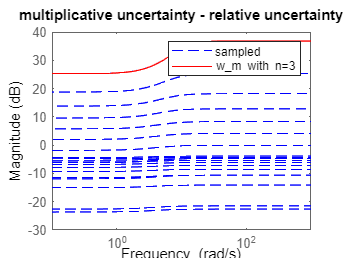

title('multiplicative uncertainty - relative uncertainty')
Leg = legend('sampled','w_m with n=3');



% controller for which the nominal closed loop system is type 1 and asymptotically stable
ContH_num = (1.792*10^4*s^2 + 2.508*10^5*s + 7.346*10^5);
ContH_den = (s^3 + 610.5*s^2 + 4.367*10^4*s + 1222);
C = ContH_num/ContH_den

C =
 
   17920 s^2 + 250800 s + 734600
  --------------------------------
  s^3 + 610.5 s^2 + 43670 s + 1222
 
Continuous-time transfer function.



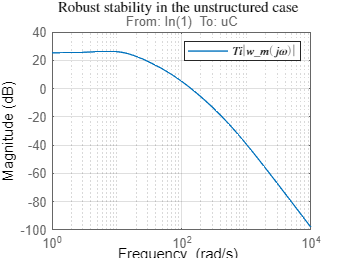

% UNSTRUCTURED case
SF=loopsens(P_nom,C);

% robust stability
bodemag(SF.Ti*w_m),grid
legend('$Ti|w_m(j\omega)|$','interpreter','latex')
title('Robust stability in the unstructured case','Interpreter','latex')

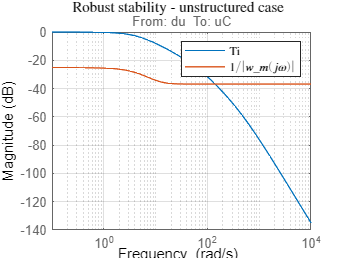

bodemag(SF.Ti,1/w_m),grid
legend('Ti','$1/|w_m(j\omega)|$','interpreter','latex')
title('Robust stability - unstructured case','Interpreter','latex')

% STRUCTURED case
SF1=loopsens(Plant,C);
[M,Delta,BlkStruct]=lftdata(SF1.Ti)

M =
 
  A = 
           x1      x2      x3      x4      x5
   x1     -10       5       0       0       0
   x2    -0.2      -4    -280  -15.31  -22.42
   x3     128       0  -610.5  -170.6  -2.387
   x4       0       0     256       0       0
   x5       0       0       0       2       0
 
  B = 
             ?        ?        ?        ?        ?        ?       du
   x1   -6.708     8.66        0        0        0   -21.21        0
   x2        0        0  -0.3464   -1.342   -2.449        0        2
   x3        0        0        0        0        0        0        0
   x4        0        0        0        0        0        0        0
   x5        0        0        0        0        0        0        0
 
  C = 
            x1       x2       x3       x4       x5
   ?    -1.342   0.6708        0        0        0
   ?         0   0.1732        0        0        0
   ?    0.1732        0        0        0        0
   ?   -0.1342   -2.683   -187.8   -10.27   -15.04
   ?         0    1.225 

BlkStruct = 5×1 struct array with fields:
    Name
    Size
    Type
    Occurrences
    Simplify



szDelta = size(Delta);
M11 = M(1:szDelta(2),1:szDelta(1));

omega = logspace(-1,6,50);
M11_g = frd(M11,omega);

mubnds = mussv(M11_g,BlkStruct);

Points completed: 50/50


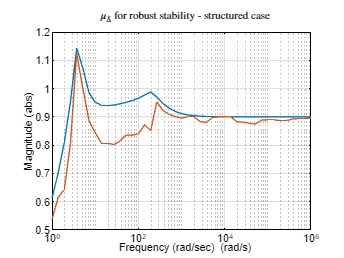


% robust stability
LinMagopt = bodeoptions;
LinMagopt.PhaseVisible = 'off'; LinMagopt.XLim = [1e0 1e6]; LinMagopt.MagUnits = 'abs';
bodeplot(mubnds(1,1),mubnds(1,2),LinMagopt),grid;
xlabel('Frequency (rad/sec)');
ylabel('Mu upper/lower bounds');
title('$\mu_{\hat \Delta}$ for robust stability - structured case','Interpreter','latex');

L_unc  = SF1.Lo;
CL_unc = feedback(L_unc,1);
opts = robOptions('Display','on','Sensitivity','on');
[stabmarg,wcu] = robstab(CL_unc,opts)

Computing peak...  Percent completed: 100/100
System is not robustly stable for the modeled uncertainty.
 -- It can tolerate up to 86.7% of the modeled uncertainty.
 -- There is a destabilizing perturbation amounting to 87.3% of the modeled uncertainty.
 -- This perturbation causes an instability at the frequency 3.75 rad/seconds.
 -- Sensitivity with respect to each uncertain element is:         
      10% for J. Increasing J by 25% decreases the margin by 2.5%. 
      5% for K. Increasing K by 25% decreases the margin by 1.25%. 
      8% for L. Increasing L by 25% decreases the margin by 2%.    
      21% for R. Increasing R by 25% decreases the margin by 5.25%.
      53% for b. Increasing b by 25% decreases the margin by 13.2%.


stabmarg = struct with fields:
           LowerBound: 0.8665
           UpperBound: 0.8734
    CriticalFrequency: 3.7493


wcu = struct with fields:
    J: 0.0357
    K: 0.0738
    L: 0.8930
    R: 0.6899
    b: 0.0430


wcu  %The variable wcu contains the combination of k and delta closest to their nominal values that causes instability

wcu = struct with fields:
    J: 0.0357
    K: 0.0738
    L: 0.8930
    R: 0.6899
    b: 0.0430



stabmarg.CriticalFrequency %the natural frequency of the unstable closed-loop pole

ans = 3.7493

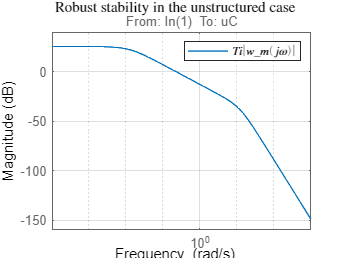

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%consider another controller%
C2 = 0.05/s;

% UNSTRUCTURED case
SF2=loopsens(P_nom,C2);
% robust stability
bodemag(SF2.Ti*w_m),grid
legend('$Ti|w_m(j\omega)|$','interpreter','latex')
title('Robust stability in the unstructured case','Interpreter','latex')

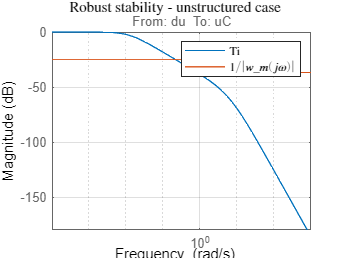

bodemag(SF2.Ti,1/w_m),grid
legend('Ti','$1/|w_m(j\omega)|$','interpreter','latex')
title('Robust stability - unstructured case','Interpreter','latex')


% STRUCTURED case
SF2=loopsens(Plant,C2);
[M2,Delta2,BlkStruct2]=lftdata(SF2.Ti)

M2 =
 
  A = 
         x1    x2    x3
   x1   -10     5     0
   x2  -0.2    -4  -0.4
   x3  0.25     0     0
 
  B = 
             ?        ?        ?        ?        ?        ?       du
   x1   -6.708     8.66        0        0        0   -21.21        0
   x2        0        0  -0.3464   -1.342   -2.449        0        2
   x3        0        0        0        0        0        0        0
 
  C = 
            x1       x2       x3
   ?    -1.342   0.6708        0
   ?         0   0.1732        0
   ?    0.1732        0        0
   ?   -0.1342   -2.683  -0.2683
   ?         0    1.225        0
   ?    0.4243        0        0
   uC        0        0      0.2
 
  D = 
             ?        ?        ?        ?        ?        ?       du
   ?      -0.9    1.162        0        0        0   -2.846        0
   ?         0        0        0        0        0        0        0
   ?         0        0        0        0        0        0        0
   ?         0        0  -0.2324     -0.9   -1.

BlkStruct2 = 5×1 struct array with fields:
    Name
    Size
    Type
    Occurrences
    Simplify



szDelta2 = size(Delta2);
M11_2 = M(1:szDelta2(2),1:szDelta2(1));
omega = logspace(-1,6,50);
M11_g_2 = frd(M11_2,omega);
mubnds2 = mussv(M11_g_2,BlkStruct2);

Points completed: 50/50


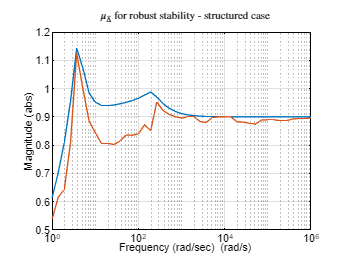


% robust stability
LinMagopt = bodeoptions;
LinMagopt.PhaseVisible = 'off'; LinMagopt.XLim = [1e0 1e6]; LinMagopt.MagUnits = 'abs';
bodeplot(mubnds2(1,1),mubnds2(1,2),LinMagopt),grid;
xlabel('Frequency (rad/sec)');
ylabel('Mu upper/lower bounds');
title('$\mu_{\hat \Delta}$ for robust stability - structured case','Interpreter','latex');


L_unc2  = SF2.Lo;
CL_unc = feedback(L_unc2,1);
opts = robOptions('Display','on','Sensitivity','on');
[stabmarg2,wcu2] = robstab(CL_unc,opts)

Computing peak...  Percent completed: 100/100
System is robustly stable for the modeled uncertainty.
 -- It can tolerate up to 108% of the modeled uncertainty.
 -- There is a destabilizing perturbation amounting to 108% of the modeled uncertainty.
 -- This perturbation causes an instability at the frequency 0.41 rad/seconds.
 -- Sensitivity with respect to each uncertain element is:         
      0% for J. Increasing J by 25% decreases the margin by 0%.    
      1% for K. Increasing K by 25% decreases the margin by 0.25%. 
      1% for L. Increasing L by 25% decreases the margin by 0.25%. 
      26% for R. Increasing R by 25% decreases the margin by 6.5%. 
      86% for b. Increasing b by 25% decreases the margin by 21.5%.


stabmarg2 = struct with fields:
           LowerBound: 1.0796
           UpperBound: 1.0819
    CriticalFrequency: 0.4100


wcu2 = struct with fields:
    J: 0.0395
    K: 0.0675
    L: 0.9868
    R: 0.3772
    b: 0.0053


wcu2  %The variable wcu contains the combination of k and delta closest to their nominal values that causes instability

wcu2 = struct with fields:
    J: 0.0395
    K: 0.0675
    L: 0.9868
    R: 0.3772
    b: 0.0053



stabmarg2.CriticalFrequency

ans = 0.4100

% add weights

Ms = power(1.0411,1/2);
B3s = 2000;
A = power(0.00000001,1/2);
wS1 = ((s/Ms+B3s)/(s+B3s*A))^2;  % performance weight

% write the augmented plant
%Use connect to build an uncertain model of the closed-loop system 
Plant.u='u'

Plant =

  Uncertain continuous-time state-space model with 1 outputs, 1 inputs, 2 states.
  The model uncertainty consists of the following blocks:
    J: Uncertain real, nominal = 0.02, variability = [-90,90]%, 1 occurrences
    K: Uncertain real, nominal = 0.1, variability = [-30,30]%, 2 occurrences
    L: Uncertain real, nominal = 0.5, variability = [-90,90]%, 1 occurrences
    R: Uncertain real, nominal = 2, variability = [-1.5,1.5], 1 occurrences
    b: Uncertain real, nominal = 0.2, variability = [-90,90]%, 1 occurrences

Type "Plant.NominalValue" to see the nominal value, "get(Plant)" to see all properties, and "Plant.Uncertainty" to interact with the uncertain elements.



Plant.y='y'

Plant =

  Uncertain continuous-time state-space model with 1 outputs, 1 inputs, 2 states.
  The model uncertainty consists of the following blocks:
    J: Uncertain real, nominal = 0.02, variability = [-90,90]%, 1 occurrences
    K: Uncertain real, nominal = 0.1, variability = [-30,30]%, 2 occurrences
    L: Uncertain real, nominal = 0.5, variability = [-90,90]%, 1 occurrences
    R: Uncertain real, nominal = 2, variability = [-1.5,1.5], 1 occurrences
    b: Uncertain real, nominal = 0.2, variability = [-90,90]%, 1 occurrences

Type "Plant.NominalValue" to see the nominal value, "get(Plant)" to see all properties, and "Plant.Uncertainty" to interact with the uncertain elements.



wS1.u='e'

wS1 =
 
  From input "e" to output:
     s^2 + 4081 s + 4.164e06
  ------------------------------
  1.041 s^2 + 0.4164 s + 0.04164
 
Continuous-time transfer function.



wS1.y='z'

wS1 =
 
  From input "e" to output "z":
     s^2 + 4081 s + 4.164e06
  ------------------------------
  1.041 s^2 + 0.4164 s + 0.04164
 
Continuous-time transfer function.



C2.u='e'

C2 =
 
  From input "e" to output:
  0.05
  ----
   s
 
Continuous-time transfer function.



C2.y='u'

C2 =
 
  From input "e" to output "u":
  0.05
  ----
   s
 
Continuous-time transfer function.



sum1=sumblk('e = r - y')

sum1 =
 
  From input "r" to output "e":
  1
 
  From input "y" to output "e":
  -1
 
Static gain.




P_aug=connect(Plant,wS1,C2,sum1,{'r'},{'z'})

P_aug =

  Uncertain continuous-time state-space model with 1 outputs, 1 inputs, 5 states.
  The model uncertainty consists of the following blocks:
    J: Uncertain real, nominal = 0.02, variability = [-90,90]%, 1 occurrences
    K: Uncertain real, nominal = 0.1, variability = [-30,30]%, 2 occurrences
    L: Uncertain real, nominal = 0.5, variability = [-90,90]%, 1 occurrences
    R: Uncertain real, nominal = 2, variability = [-1.5,1.5], 1 occurrences
    b: Uncertain real, nominal = 0.2, variability = [-90,90]%, 1 occurrences

Type "P_aug.NominalValue" to see the nominal value, "get(P_aug)" to see all properties, and "P_aug.Uncertainty" to interact with the uncertain elements.



%The structured singular value, or μ, is the mathematical tool used by robstab to compute the robust stability margin. If you are comfortable with structured singular value analysis, 
% you can use the mussv function directly to compute mu as a function of frequency and reproduce the results above. The function mussv is the underlying engine for all robustness analysis commands.
%To use mussv, we first extract the (M,Delta) decomposition of the uncertain closed-loop model ClosedLoop, where Delta is a block-diagonal matrix of (normalized) uncertain elements. The 3rd output argument of lftdata, BlkStruct, describes the block-diagonal structure of Delta and can be used directly by mussv

[M1,Delta1,BlkStruct1]=lftdata(P_aug)

M1 =
 
  A = 
          x1     x2     x3     x4     x5
   x1    -10      5      0      0      0
   x2   -0.2     -4      0      0    0.4
   x3  -4096      0   -0.4  -0.16      0
   x4      0      0   0.25      0      0
   x5  -0.25      0      0      0      0
 
  B = 
             ?        ?        ?        ?        ?        ?        r
   x1   -6.708     8.66        0        0        0   -21.21        0
   x2        0        0  -0.3464   -1.342   -2.449        0        0
   x3        0        0        0        0        0        0     4096
   x4        0        0        0        0        0        0        0
   x5        0        0        0        0        0        0     0.25
 
  C = 
           x1       x2       x3       x4       x5
   ?   -1.342   0.6708        0        0        0
   ?        0   0.1732        0        0        0
   ?   0.1732        0        0        0        0
   ?  -0.1342   -2.683        0        0   0.2683
   ?        0    1.225        0        0        0
   ?   0

BlkStruct1 = 5×1 struct array with fields:
    Name
    Size
    Type
    Occurrences
    Simplify



%For robust stability analysis, only the channels of M associated with the uncertainty channels are used. Based on the row/column size of Delta, select the proper columns and rows of M. Remember that the rows of Delta correspond to the columns of M, and vice versa. Consequently, the column dimension of Delta is used to specify the rows of M:
szDelta1 = size(Delta1);
M11_1 = M1(1:szDelta1(2),1:szDelta1(1));

%In its simplest form, mu-analysis is performed on a finite grid of frequencies. Pick a vector of logarithmically-spaced frequency points and evaluate the frequency response of M11 over this frequency grid.
omega = logspace(-1,6,50);
M11_g1 = frd(M11_1,omega);

%Compute mu(M11) at these frequencies and plot the resulting lower and upper bounds:
mubnds1 = mussv(M11_g1,BlkStruct1);

Points completed: 50/50


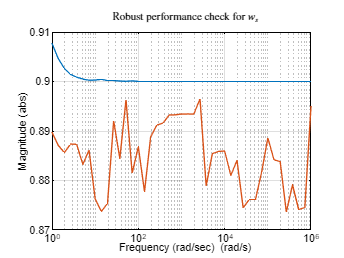


% robust performance check (Structured case)
LinMagopt = bodeoptions;
LinMagopt.PhaseVisible = 'off'; LinMagopt.XLim = [1e0 1e6]; LinMagopt.MagUnits = 'abs';
bodeplot(mubnds1(1,1),mubnds1(1,2),LinMagopt),grid;
xlabel('Frequency (rad/sec)');
ylabel('Mu upper/lower bounds');
title('Robust performance check for $w_s$','Interpreter','latex');

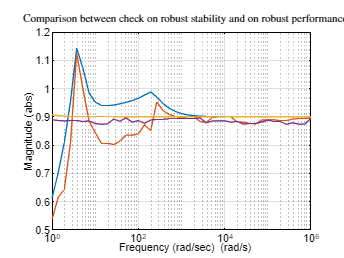


% bodeplot(mubnds(1,1),mubnds(1,2),mubnds1(1,1),mubnds1(1,2),LinMagopt),grid;
% xlabel('Frequency (rad/sec)');
% ylabel('Mu upper/lower bounds');
% title('Comparison between check on robust stability and on robust performance','interpreter','latex');


%For the nominal values of the uncertain elements k and delta, the closed-loop gain is less than 1:
getPeakGain(P_aug.NominalValue)

ans = 9.2325e+07


%This says that the controller K meets the disturbance rejection and noise insensitivity goals. But is this nominal performance maintained in the face of the modeled uncertainty? This question is best answered with robgain.
opt = robOptions('Display','on');
[perfmarg,wcu] = robgain(P_aug,1,opt);

The performance margin is 0 since the nominal gain exceeds 1.
